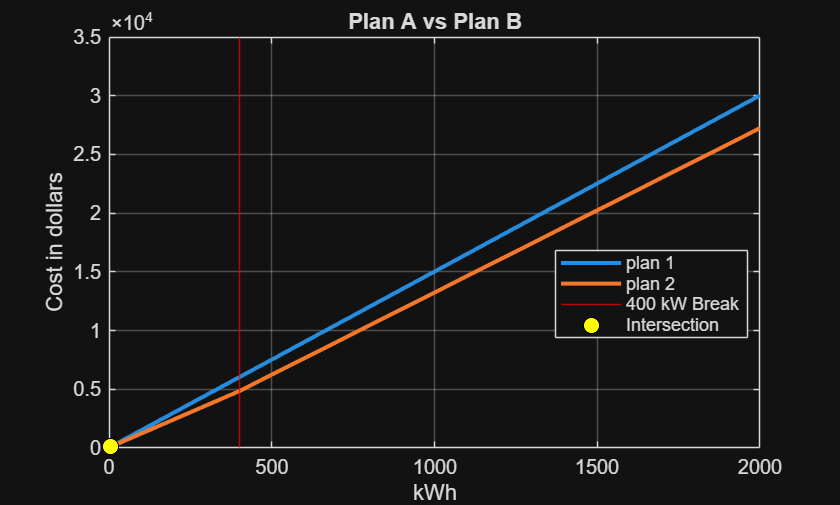

clc; clear; clear all
prompt = {'Enter starting value:', 'Enter step size:', 'Enter ending value:'};
dlgtitle = 'Input for x vector';
dims = [1 35];
definput = {'0','25','800'};   % default values

answer = inputdlg(prompt, dlgtitle, dims, definput);

startVal = str2double(answer{1});
stepVal  = str2double(answer{2});
endVal   = str2double(answer{3});

x = startVal:stepVal:endVal;


C = zeros(size(x));

y1 = 15*x + 25;
eq1 = (x <= 400);
eq2 = (x > 400);

y2 = zeros(size(x)); % Initialize y2 for both conditions
y2(eq1) = 12*x(eq1) + 40;   % Apply first equation for x <= 400
y2(eq2) = 14*x(eq2) + (40 - 2 * 400); % Apply second equation for x > 400
plot(x, y1, 'LineWidth', 2)
hold on
plot(x, y2, 'LineWidth', 2)
grid on
xline(400, 'r-');

legend('plan 1', 'plan 2', '400 kW Break', 'Location', 'best');
xlabel('kWh');
ylabel('Cost in dollars');
title('Plan A vs Plan B');

x_int = 5;
y_int = 15*x_int + 25;

hPoint = plot(x_int, y_int, 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'y', 'DisplayName', 'Intersection');


usage = (0:100:900)';  % 10 rows

% Plan A
planA = 15*usage + 25;

% Plan B (piecewise)
planB = zeros(size(usage));
eq1 = usage <= 400;
eq2 = usage > 400;

planB(eq1) = 12*usage(eq1) + 40;
planB(eq2) = 14*usage(eq2) - 760;

T = table(usage, planA, planB, 'VariableNames', {'Usage_kW', 'PlanA_Cost', 'PlanB_Cost'});

disp(T);

    Usage_kW    PlanA_Cost    PlanB_Cost
    ________    __________    __________

        0            25            40   
      100          1525          1240   
      200          3025          2440   
      300          4525          3640   
      400          6025          4840   
      500          7525          6240   
      600          9025          7640   
      700         10525          9040   
      800         12025         10440   
      900         13525         11840   





% --- Recommendation text ---
fprintf('\nRECOMMENDATION:\n');


RECOMMENDATION:


fprintf('----------------------------------------\n');

----------------------------------------


fprintf('The two plans have the same cost at x = %.2f kW.\n', x_int);

The two plans have the same cost at x = 5.00 kW.


fprintf('For usage below this point, Plan A is slightly cheaper.\n');

For usage below this point, Plan A is slightly cheaper.


fprintf('For usage above this point, Plan B is cheaper.\n\n');

For usage above this point, Plan B is cheaper.




if x_int < 0 || x_int > 400
    fprintf('However, based on realistic usage levels, Plan B is generally the better choice.\n');
else
    fprintf('Since typical usage is well above %.2f kW, customers should choose Plan B.\n', x_int);
end

Since typical usage is well above 5.00 kW, customers should choose Plan B.


fprintf('----------------------------------------\n\n');

----------------------------------------

